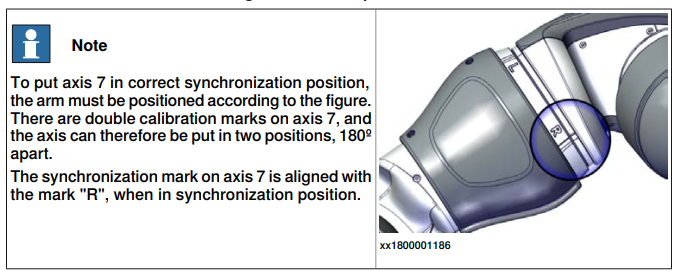

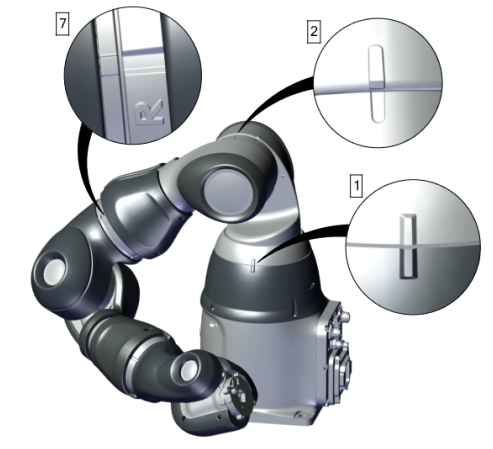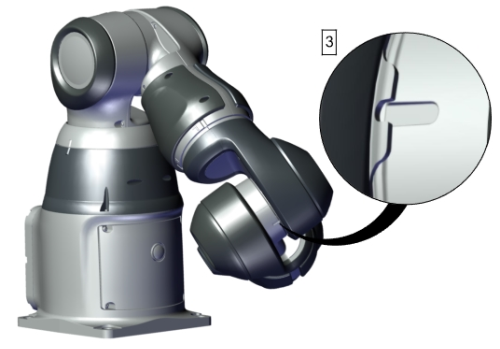

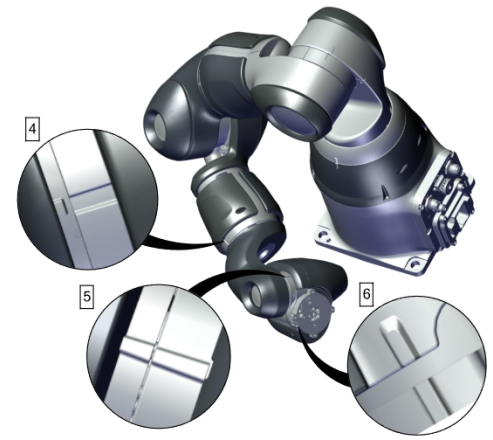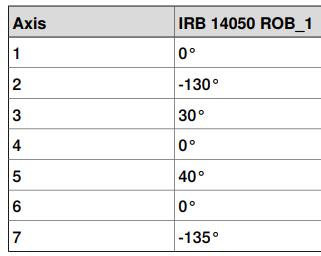

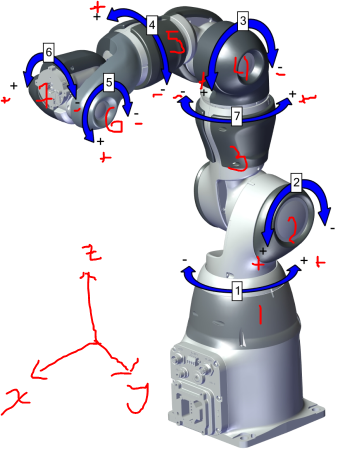

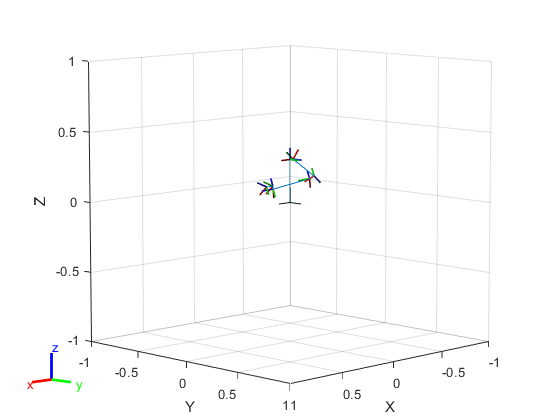

scala=1000;
%creacion cuerpo rigido 1
b1 = rigidBody('b1');
%creacion de las articulaciones 
j1 = rigidBodyJoint('j1','revolute');
j1.HomePosition = 0;
T01 = trvec2tform([0, 0, 305.83/scala])*trotz(0,'deg'); % calibración de 0°
setFixedTransform(j1,T01);
b1.Joint = j1;
%creacion de un arbol rigido 
robot = rigidBodyTree;
%aÃ±adir el cuerpo al arbol
addBody(robot,b1,'base')


%creacion  cuerpo 2 
b2 = rigidBody('b2');
j2 = rigidBodyJoint('j2','revolute');
j2.HomePosition = 0; % User defined
T12 = trvec2tform([-30/scala, 0, 0])*trotx(-pi/2)*trotz(-130,'deg'); % calibración de -130°
setFixedTransform(j2,T12);
b2.Joint = j2;
addBody(robot,b2,'b1'); % Add body2 to body1

%creacion  cuerpo 3
b3 = rigidBody('b3');
j3 = rigidBodyJoint('j3','revolute');
j3.HomePosition = 0; % User defined
T23 = trvec2tform([30/scala, 0, 0])*trotx(pi/2)*trvec2tform([0, 0, 251.52/scala])*trotz(-135,'deg'); % calibración de -135°
setFixedTransform(j3,T23);
b3.Joint = j3;
addBody(robot,b3,'b2'); % Add body3 to body2

%creacion  cuerpo 4
b4 = rigidBody('b4');
j4 = rigidBodyJoint('j4','revolute');
j4.HomePosition = 0; % User defined
T34 = trvec2tform([38.51/scala, 0, 0])*trotx(-pi/2)*trvec2tform([0, 0, 0])*trotz(-pi/2)*trotz(30,'deg'); % calibración de 30°
setFixedTransform(j4,T34);
b4.Joint = j4;
addBody(robot,b4,'b3'); % Add body4 to body3

%creacion  cuerpo 5
b5 = rigidBody('b5');
j5 = rigidBodyJoint('j5','revolute');
j5.HomePosition = 0; % User defined
T45 = trvec2tform([42.37/scala, 0, 0])*trotx(-pi/2)*trvec2tform([0, 0, 267.01/scala])*trotz(0); % calibración de 0°
setFixedTransform(j5,T45);
b5.Joint = j5;
addBody(robot,b5,'b4'); % Add body5 to body4

%creacion  cuerpo 6
b6 = rigidBody('b6');
j6 = rigidBodyJoint('j6','revolute');
j6.HomePosition = 0; % User defined
T56 = trvec2tform([-28.8/scala, 0, 0])*trotx(pi/2)*trvec2tform([0, 0, 0])*trotz(40,'deg'); % calibración de 40°
setFixedTransform(j6,T56);
b6.Joint = j6;
addBody(robot,b6,'b5'); % Add body6 to body5

%creacion  cuerpo 7
b7 = rigidBody('b7');
j7 = rigidBodyJoint('j7','revolute');
j7.HomePosition = 0; % User defined
T67 = trvec2tform([27.24/scala, 0, 0])*trotx(-pi/2)*trvec2tform([0, 0, 35.85/scala])*trotz(0); % calibración de 0°
setFixedTransform(j7,T67);
b7.Joint = j7;
addBody(robot,b7,'b6'); % Add body7 to body6



%%Efector final 
% bodyEndEffector = rigidBody('endeffector');
% tform5 = trvec2tform([0.5, 0, 0]); % User defined
% setFixedTransform(bodyEndEffector.Joint,tform5);
% addBody(robot,bodyEndEffector,'body4');

show(robot);

Resultados